### **Ejercicio 1**

#### **Solución Analitica**

% Limpieza del espacio de trabajo
clearvars; % Borramos solo las variables del workspace
clf; % Borramos el area de las graficas


fo = @(x) -0.5.*x.^4 + 4.*x.^3 - 10.*x.^2 + 8.5.*x + 1;


#### Solucion Numerica

inicio = 0;
fin = 4;
h = 0.5;
x_i = 0;
y_i = 1;

fd = @(x,y) -2*x.^3 + 12*x.^2 - 20.*x +8.5; 

[x,y] = RK_4(fd, h, inicio ,fin , x_i,y_i)

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


y =     1.0000    3.2188    3.0000    2.2188    2.0000    2.7188    4.0000    4.7188    3.0000


fprintf('Los valores evaluados de RK4 son = %8.6f\n',y);

Los valores evaluados de RK4 son = 1.000000
Los valores evaluados de RK4 son = 3.218750
Los valores evaluados de RK4 son = 3.000000
Los valores evaluados de RK4 son = 2.218750
Los valores evaluados de RK4 son = 2.000000
Los valores evaluados de RK4 son = 2.718750
Los valores evaluados de RK4 son = 4.000000
Los valores evaluados de RK4 son = 4.718750
Los valores evaluados de RK4 son = 3.000000


fprintf('Los valores evaluados de la funcion original son = %8.6f\n',(fo(x)));

Los valores evaluados de la funcion original son = 1.000000
Los valores evaluados de la funcion original son = 3.218750
Los valores evaluados de la funcion original son = 3.000000
Los valores evaluados de la funcion original son = 2.218750
Los valores evaluados de la funcion original son = 2.000000
Los valores evaluados de la funcion original son = 2.718750
Los valores evaluados de la funcion original son = 4.000000
Los valores evaluados de la funcion original son = 4.718750
Los valores evaluados de la funcion original son = 3.000000


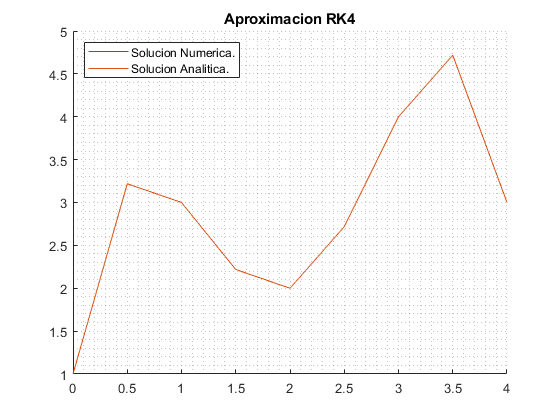

hold on;
plot(x,y,"DisplayName","Solucion Numerica.");
plot(x,fo(x),"DisplayName","Solucion Analitica.");
hold off;
grid minor;
legend("location","northwest");
title("Aproximacion RK4")

### **Ejercicio 2**

#### **Solucion Analitica**

% Limpieza del espacio de trabajo
clearvars; % Borramos solo las variables del workspace
clf; % Borramos el area de las graficas


fo = @(x) (4/1.3)*(exp(0.8*x)-exp(-0.5*x)) + 2*exp(-0.5*x);


#### Solucion Numerica

inicio = 0;
fin = 4;
h = 1;
x_i = 0;
y_i = 2;

fd = @(x,y) 4*exp(0.8*x) - 0.5*y; 

[x,y] = RK_4(fd, h, inicio ,fin , x_i,y_i)

x =      0     1     2     3     4


y =     2.0000    6.2010   14.8625   33.7213   75.4392


fprintf('Los valores evaluados de RK4 son = %8.6f\n',y);

Los valores evaluados de RK4 son = 2.000000
Los valores evaluados de RK4 son = 6.201037
Los valores evaluados de RK4 son = 14.862484
Los valores evaluados de RK4 son = 33.721348
Los valores evaluados de RK4 son = 75.439172


fprintf('Los valores evaluados de la funcion original son = %8.6f\n',(fo(x)));

Los valores evaluados de la funcion original son = 2.000000
Los valores evaluados de la funcion original son = 6.194631
Los valores evaluados de la funcion original son = 14.843922
Los valores evaluados de la funcion original son = 33.677172
Los valores evaluados de la funcion original son = 75.338963


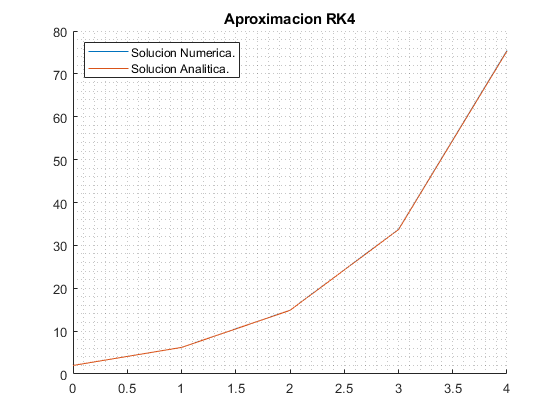

hold on;
plot(x,y,"DisplayName","Solucion Numerica.");
plot(x,fo(x),"DisplayName","Solucion Analitica.");
hold off;
grid minor;
legend("location","northwest");
title("Aproximacion RK4")

#### Metodo RK4

function [x,y] = RK_4(f, h, inicio ,fin , val_ix,val_iy)
x = inicio:h:fin;
y = zeros(1,length(x));
y(1) = val_iy;
x(1) = val_ix;
    for i=1:(length(x)-1)
        k_1 = f(x(i), y(i));
        k_2 = f(x(i) + (1/2)*h, y(i) + (1/2)*h * k_1);
        k_3 = f(x(i) + (1/2)*h, y(i) + (1/2)*h * k_2);
        k_4 = f(x(i) + h, y(i) + k_3 * h);
        
        y(i+1) = y(i) + (1/6)*(k_1 + 2*k_2+2*k_3+k_4)*h;
    end
end